clear; close all;
rng(100);
X1 = mvnrnd([1 3],[1 0; 0 1],60); 
X2 = mvnrnd([4 1],[2 0; 0 2],40);
X = [X1; X2];
y1 = ones(size(X1,1),1); y2 = -ones(size(X2,1),1);
y = [y1; y2];
feature = size(X,2);
N = size(X,1);
C = 10; % C = 100;
sigma1 = 1.75;

Kernel = zeros(N);
for i=1:N
    for j=1:N
        Kernel(i,j) = exp( (-(norm( X(i,:) - X(j,:) )) ^ 2) / (2 * (sigma1 ^ 2)));
    end
end

yy = y*y';
H = (yy.*(Kernel));
f = -ones(N,1);
A = [-eye(N); eye(N)];
b = [zeros(N,1); C*ones(N,1)];
Aeq = y';
beq = 0;


lamda = quadprog(H,f,A,b,Aeq,beq); 


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


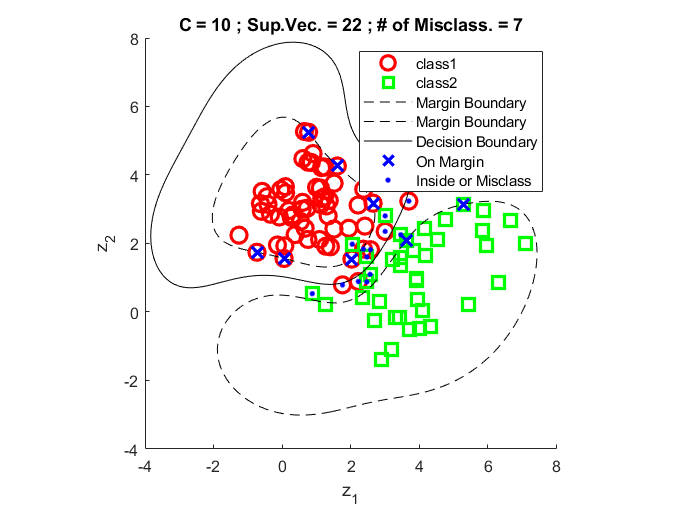


SV = find(lamda>0.001);                      % SV
nSV = numel(SV);
SV_1 = find(lamda < (C*0.99) & lamda>0.001); % SV on the margins
SV_2 = find(lamda > (C*0.99));               % SV between margins

w = (lamda.*y)'*Kernel;
bias = zeros(numel(SV_1),1);
for i=1 : numel(SV_1)
    w0 = 1/y(SV_1(i)) - w(SV_1(i));
    bias(i,1) = w0;
end
w0 = mean(bias);

% ploting

m1 = linspace(-4,8,N);
m2 = linspace(-4,8,N);
[grid1,grid2] = meshgrid(m1, m2);
grid = [grid1(:),grid2(:)];

g = zeros(size(grid,1),1);
for i=1:size(grid,1)
    g1 = 0;
    for j=1:N
        g1 = g1+ lamda(j)*y(j) * exp( - (norm( X(j,:)-grid(i,:) ) ^2) / (2*sigma1^2));
    end
    g(i,1) = g1+w0;
end
g = reshape(g,size(grid1));

decision = ((lamda.*y)'*Kernel +w0)'.*y;
count = sign(decision);
misclass = sum(count(:)==-1);

figure;
hold on
plot(X1(:,1),X1(:,2), 'or',...
    X2(:,1),X2(:,2), 'sg',...
    'LineWidth',2,...
    'MarkerSize', 10);
contour(grid1,grid2, g,[1 1], '--k');
contour(grid1,grid2, g, [-1 -1],'--k');
contour(grid1,grid2, g, [0 0],'k');
plot(X(SV_1,1),X(SV_1,2), 'xb',...
    X(SV_2,1),X(SV_2,2), '.b',...
    'LineWidth',2, 'MarkerSize', 10);
title(['C = ', num2str(C), ' ; ', 'Sup.Vec. = ',num2str(nSV),' ; # of Misclass. = ', num2str(misclass)]);
legend({'class1','class2',...
    'Margin Boundary','Margin Boundary','Decision Boundary',...    
    'On Margin', 'Inside or Misclass'},'Location','northeast')
axis equal
xlabel('z_{1}'); ylabel('z_{2}');
hold off